addpath ../fieldtrip-20240110

let's write up the following simulation

**x(t) = 0.8x(t-1) - 0.5x(t-1)**

this implies that x only depends on prior values of itself

**y(t) = 0.9y(t-1) + 0.5z(t-1) - 0.8y(t-1)**

this equation would then imply that y depends on its two previous values

and the most recent value of z

**z(t) = 0.5z(t-1) + 0.4x(t-1) - .2z(t-2)**

so Z depends on its last 2 values and x's most recent value

** x -> z**

** z->y**

cfg = [];
cfg.ntrials = 500;
cfg.triallength =1;
cfg.fsample = 200;
cfg.nsignal =3;
cfg.method = 'ar'

cfg = struct with fields:
        ntrials: 500
    triallength: 1
        fsample: 200
        nsignal: 3
         method: 'ar'


% t-1
cfg.params(:,:,1) = [0.8, 0  0;
                     0  0.9 0.5;
                     0.4  0  0.5];
%t-2
cfg.params(:,:,2) = [-0.5    0    0 ;
                        0 -0.8    0 ;
                        0    0 -0.2];

cfg.noisecov      = [ 0.3    0    0 ;
                        0    1    0 ;
                        0    0  0.2];
%noise sources are all independent
data              = ft_connectivitysimulation(cfg);

the call to "ft_connectivitysimulation" took 0 seconds and required the additional allocation of an estimated NaN MB


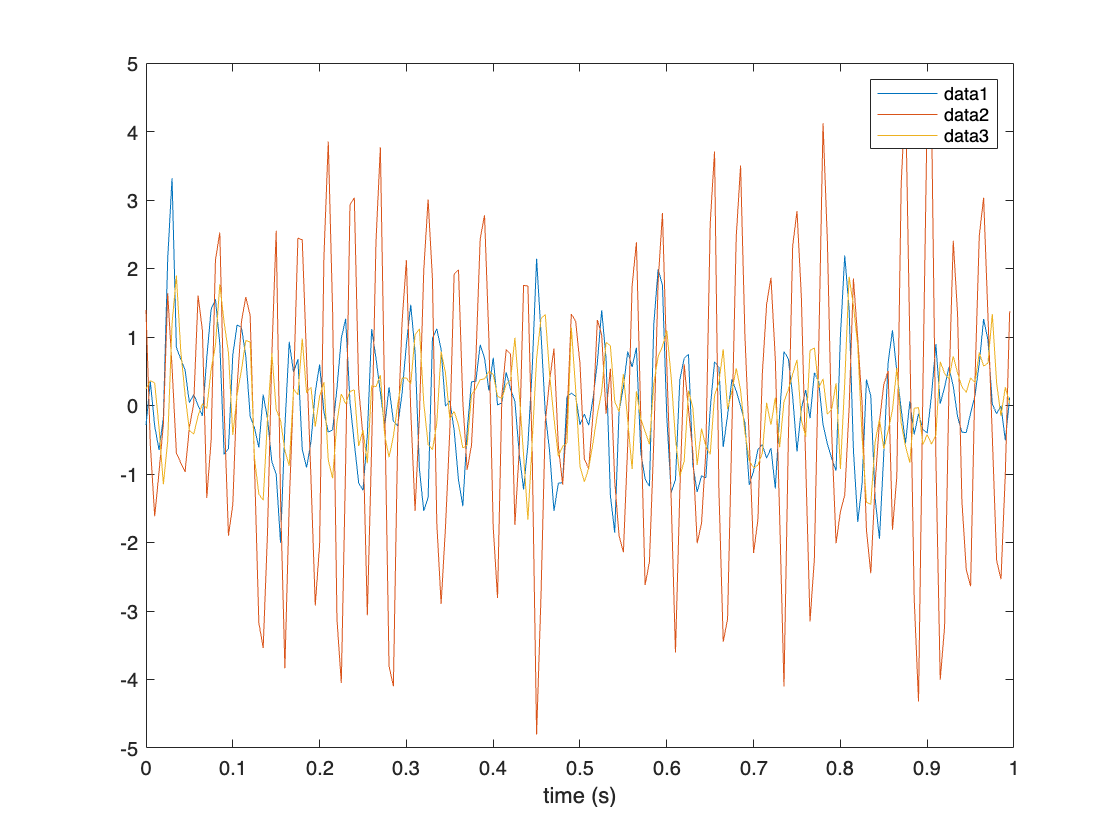

%Simulated data consists of 3 channels (cfg.nsignal) in 500 trials
%(cfg.ntrials), 
% Q:does that mean we have 500 samples ? if so I would expect 2.5 seconds
% of data?
% A: No! We specified a trial length of 1 second, but we did start this
% process from the jump 500 different times. 
figure 
plot(data.time{1}, data.trial{1})
xlabel("time (s)")
legend

**Digression on Phase and Amplitude Envelopes Leading to a visual Example of the HIlbert Transform**

data_hilbert = hilbert(data.trial{1}(1,:)); % Apply Hilbert Transform
phase = angle(data_hilbert); % Extract phase angles in radians
plot(data.time{1},[data.trial{1}(1,:); phase])
legend

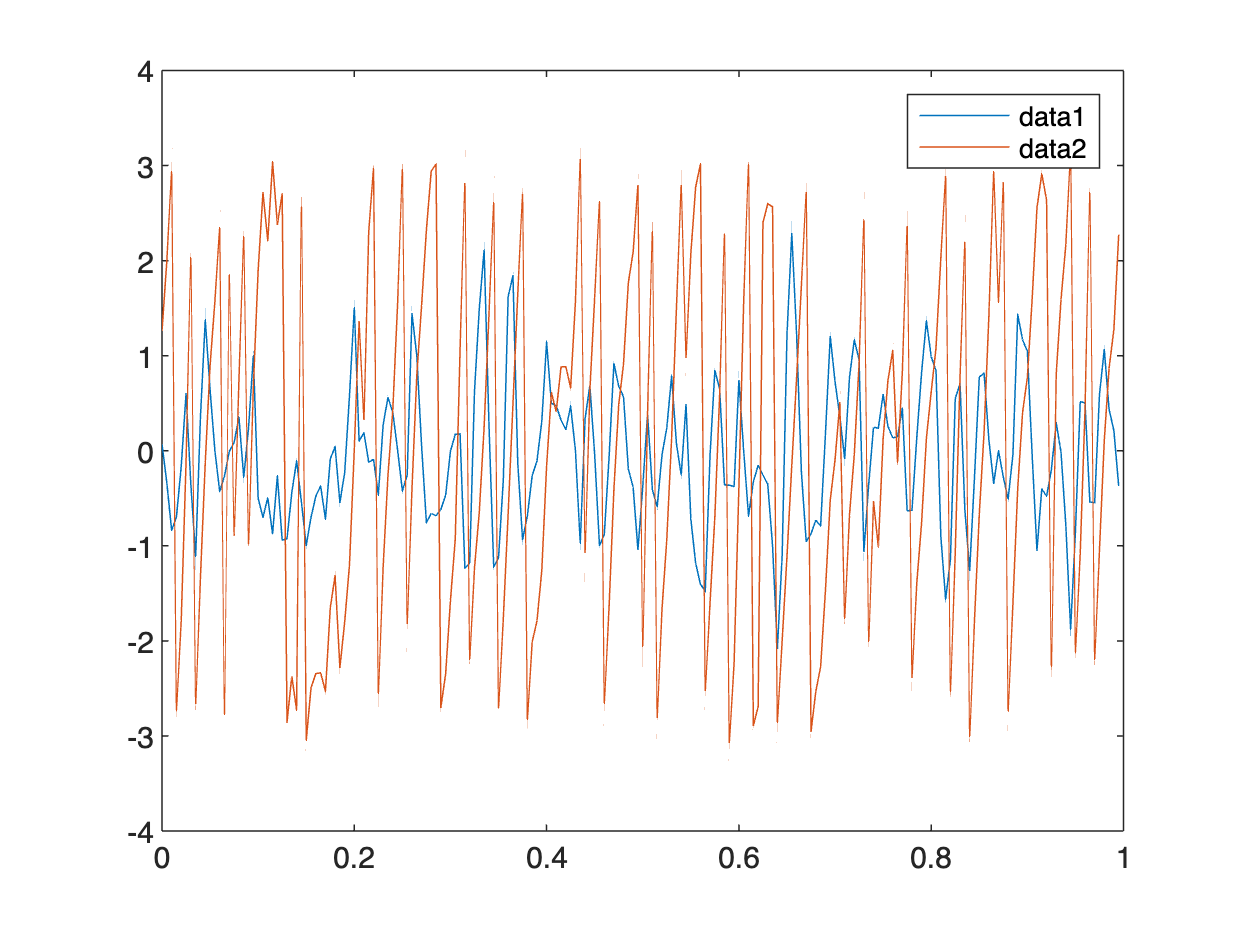

% Generate a 10 Hz sine wave
fs = 1000; % Sampling frequency

t = 0:1/fs:1; % Time vector
signal = sin(2 * pi * 10 * t); % 10 Hz sine wave

% Apply Hilbert Transform
analytic_signal = hilbert(signal); 

% Extract amplitude and phase
amplitude = abs(analytic_signal); % Envelope
phase = angle(analytic_signal);   % Phase in radians

% Plot results
figure;
subplot(3,1,1); plot(t, signal); title('Original Signal');
subplot(3,1,2); plot(t, amplitude); title('Amplitude Envelope');
subplot(3,1,3); plot(t, phase); title('Instantaneous Phase');

**Resuming Field trip tutorial**

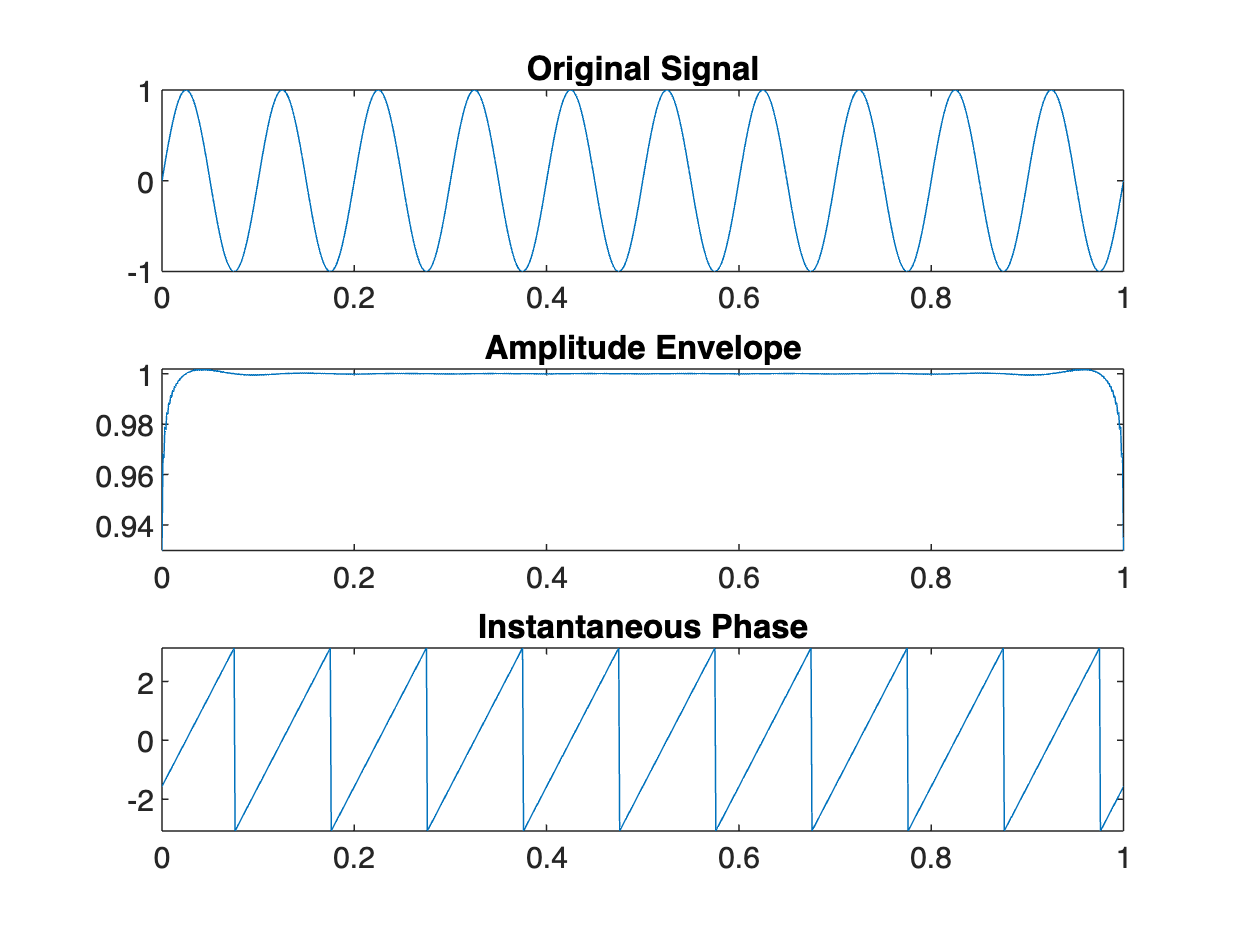

%looking through the complete data using
cfg =[];
cfg.viewmode ='vertical'; % may also specifcy butterfuly

ft_databrowser(cfg,data);

% In order to get spectrally decomposed granger causality, we're going to
% need to compute the spectral transfer matrix and the covairance of an
% autoregressive model's residual's
cfg = [];
cfg.order = 5;
cfg.toolbox = 'bsmart';

the input is raw data with 3 channels and 500 trials


 In fixsampleinfo at line 92
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279
 In ft_databrowser at line 340



detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


%feeding in data from above simulation
mdata = ft_mvaranalysis(cfg, data)
mdata.coeffs

**Exercise 1 **compare the parameters specified for the simulation with the estimated coefficients and discuss.

**% t-1 **        ** Ground Truth**              |   **Estimated Params**

cfg.params(:,:,1) = [0.8, 0  0;          |  ` 0.7990    0.0017    0.0040`

                              0  0.9 0.5;         | ` 0.0014    0.8901    0.5096`

                             0.4  0  0.5];        | ` 0.3993    0.0009    0.4940`

`Found spurrious coefficients between x and y albeit quite small,`

`very nearly spot on with x->z 0.4 vs .3993, and z->y 0.5 vs .5096.`

`Autoregressive coefficients are really close.`

**%t-2         ** ** Ground Truth**              |   **Estimated Params**

cfg.params(:,:,2) = [-0.5    0    0 ;    |`   -0.5020   -0.0031   -0.0068`

                                 0  -0.8    0 ;    |        `0.0010   -0.7925   -0.0045`

                                0    0   -0.2];    |  `   0.0022   -0.0034   -0.1952`

`found verrrry small cross relationships, all smaller than .01`

`Higher orders all less than .01, found quite small coefficients. `

`This could be a problem when small connection have low magnitude contribution`

`t-3`

`    0.0033    0.0005    0.0082`

`    0.0005   -0.0103    0.0076`

`    0.0024    0.0023   -0.0062`

`t-4`

`   -0.0079    0.0008   -0.0118`

`    0.0105    0.0033   -0.0080`

`   -0.0032   -0.0004   -0.0008`

`t-5`

`    0.0048   -0.0039   -0.0015`

`   -0.0045   -0.0047    0.0138`

`    0.0034   -0.0017   -0.0050`

`I bet AIC or BIC would cull these order parameters out`

%computing the parametric spectral transfer matrix
cfg             = [];
cfg.method      = 'mvar';
mfreq           = ft_freqanalysis(cfg, mdata);
mfreq
% Q; how are there 101 frequencies in decomposition if our model order is

 In ft_mvaranalysis at line 105



 In fixsampleinfo at line 92
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279
 In ft_mvaranalysis at line 124



 In fixsampleinfo at line 105
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279
 In ft_mvaranalysis at line 124

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
preprocessing
preprocessing trial 500 from 500

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated NaN MB

the call to "ft_mvaranalysis" took 1 seconds and required the additional allocation of an estimated NaN MB


mdata = struct with fields:
         dimord: 'chan_chan_lag'
          label: {3×1 cell}
         coeffs: [3×3×5 double]
       noisecov: [3×3 double]
            dof: 500
    fsampleorig: 200
            cfg: [1×1 struct]


% 5? Model order relates to the order of the polynomial in the z-transform

ans = ans(:,:,1) =

    0.7980   -0.0002    0.0027
    0.0009    0.8956    0.4951
    0.3972   -0.0007    0.4927


ans(:,:,2) =

   -0.4987    0.0011   -0.0011
    0.0028   -0.8049    0.0120
    0.0014   -0.0021   -0.1993


ans(:,:,3) =

   -0.0065   -0.0018   -0.0068
   -0.0087   -0.0024    0.0040
    0.0004    0.0008   -0.0100


ans(:,:,4) =

    0.0009    0.0025    0.0052
    0.0169    0.0001    0.0041
    0.0019   -0.0006   -0.0006


ans(:,:,5) =

   -0.0045   -0.0021   -0.0087
   -0.0108   -0.0070    0.0041
    0.0081   -0.0011   -0.0036


% not the number of time points

% non-parametric computation of the cross-spectral density matrix
cfg         = [];
cfg.method  = 'mtmfft';
cfg.taper   = 'dpss';

the input is mvar data
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
computing MAR-model based TFR


cfg.output  = 'fourier';
cfg.tapsmofrq = 2;
freq = ft_freqanalysis(cfg, data);
freq

**Computation and Inspection of the connectivity measures**

cfg     = [];
cfg.method = 'coh';
coh = ft_connectivityanalysis(cfg, freq);
cohm = ft_connectivityanalysis(cfg, mfreq);

%visualizing the parametric data
figure

the input is raw data with 3 channels and 500 trials


 In fixsampleinfo at line 92
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279
 In ft_freqanalysis at line 243



 In fixsampleinfo at line 105
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279
 In ft_freqanalysis at line 243

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 500/500 nfft: 200 samples, datalength: 200 samples, 3 tapers

the call to "ft_freqanalysis" took 0 seconds and required the additional allocation

cfg           = [];

freq = struct with fields:
            label: {3×1 cell}
           dimord: 'rpttap_chan_freq'
             freq: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 … ] (1×101 double)
    fourierspctrm: [1500×3×101 double]
        cumsumcnt: [500×1 double]
        cumtapcnt: [500×1 double]
              cfg: [1×1 struct]


cfg.parameter = 'cohspctrm';
cfg.zlim      = [0 1];
ft_connectivityplot(cfg, coh, cohm);

I am noticing that the parametric crossspectral density as computed as the coherence of the cross spectrum, is showing a much smoother cross spectral connectivity compared to the fourier decomposition. 

**Interpretation of the cross spectral coherence:**

- **Signal 1->Signal 2 **is showing a peak in the 0-30Hz band suggesting that they are both oscillating in this range.

- **Signal 1->3 **I see a higher broadband across all powers for Signal 1->3 and a similar peak in 0-30Hz. I wonder if X was connected directly to Z, This may explain the higher connectivity in this band As a matter of fact this broad high connectivity may be exactly why PDC is the same across bands. 

- **Signal 2->3: I **see a broader shift compared to the lil 1-2 liil connection. Since this measure is symmetric, I am seeing the same shape on  on **3->2** which is showing me that Z-.Y is a possible connection. However this metric would have no means of distinguishing z->Y  vs y->z

**Ground Truth: **

** x -> z**

** z->y**

**Note: **This metric is asserting that x-.y is a direct connection. While Y is in fact influenced by the state of x, it is mediated through the signal Z. Thus this is picking up an indirect connection, albeit the whold 'gram is lower 

***Question: If the model order was specified as 5, how is it possible that I am seeing connectivity between 0-100Hz. For a signal with sampling rate of 200Hz I would expect 5 samples to offer me the a lower bound of 40Hz, because that is .025 seconds of data, which can capture one full oscillation of 40Hz? Is that right? ***

**Granger Connectivity**

cfg           = [];

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


cfg.method    = 'granger';

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


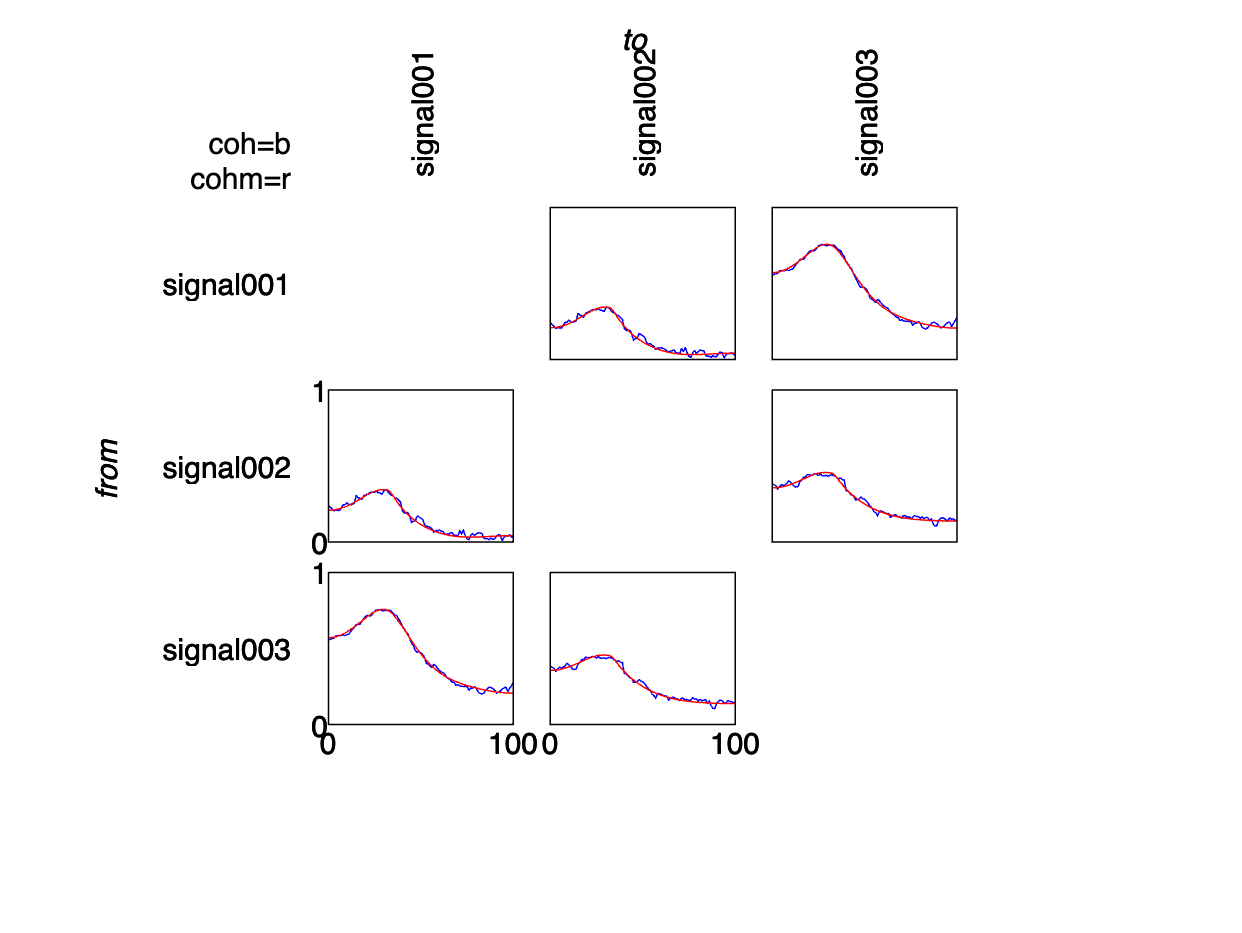

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityplot" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityplot" took 0 seconds and required the additional allocation of an estimated NaN MB


granger       = ft_connectivityanalysis(cfg, mfreq);

cfg           = [];
cfg.method    = 'granger';
fgranger      = ft_connectivityanalysis(cfg, freq)
cfg           = [];
cfg.parameter = 'grangerspctrm';

cfg.zlim      = [0 1];


ft_connectivityplot(cfg, granger, fgranger);

The granger causality cross spectrogram has succesfully found X->Z and Z.>Y, however it has still latched onto the X->Y. Given that X is upstream this may be expected, however the strange thing here is that X->Z is 0.4, but Z->Y is 0.5. Meaning that Y's state is more strongly influenced by Z than Z is influenced by X.

Another thing I notice is that for X's directed connections the broad spectrum is much lower. The peaks are sharper around 10-30Hz for X->Z. 

Observation3: difference between parametric and non-parametric decomposition appear trivial here.

**More Plots**

figure
for row=1:3
for col=1:3

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


  subplot(3,3,(row-1)*3+col);
  plot(granger.freq, squeeze(granger.grangerspctrm(row,col,:)))
  ylim([0 1])
end

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
computing multivariate non-parametric spectral factorization on 3 channels
the call to "ft_connectivityanalysis" took 0 seconds and required the additional allocation of an estimated NaN MB


fgranger = struct with fields:
            label: {3×1 cell}
           dimord: 'chan_chan_freq'
    grangerspctrm: [3×3×101 double]
             freq: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 … ] (1×101 double)
              cfg: [1×1 struct]


end


**PDC**

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityplot" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityplot" took 0 seconds and required the additional allocation of an estimated NaN MB


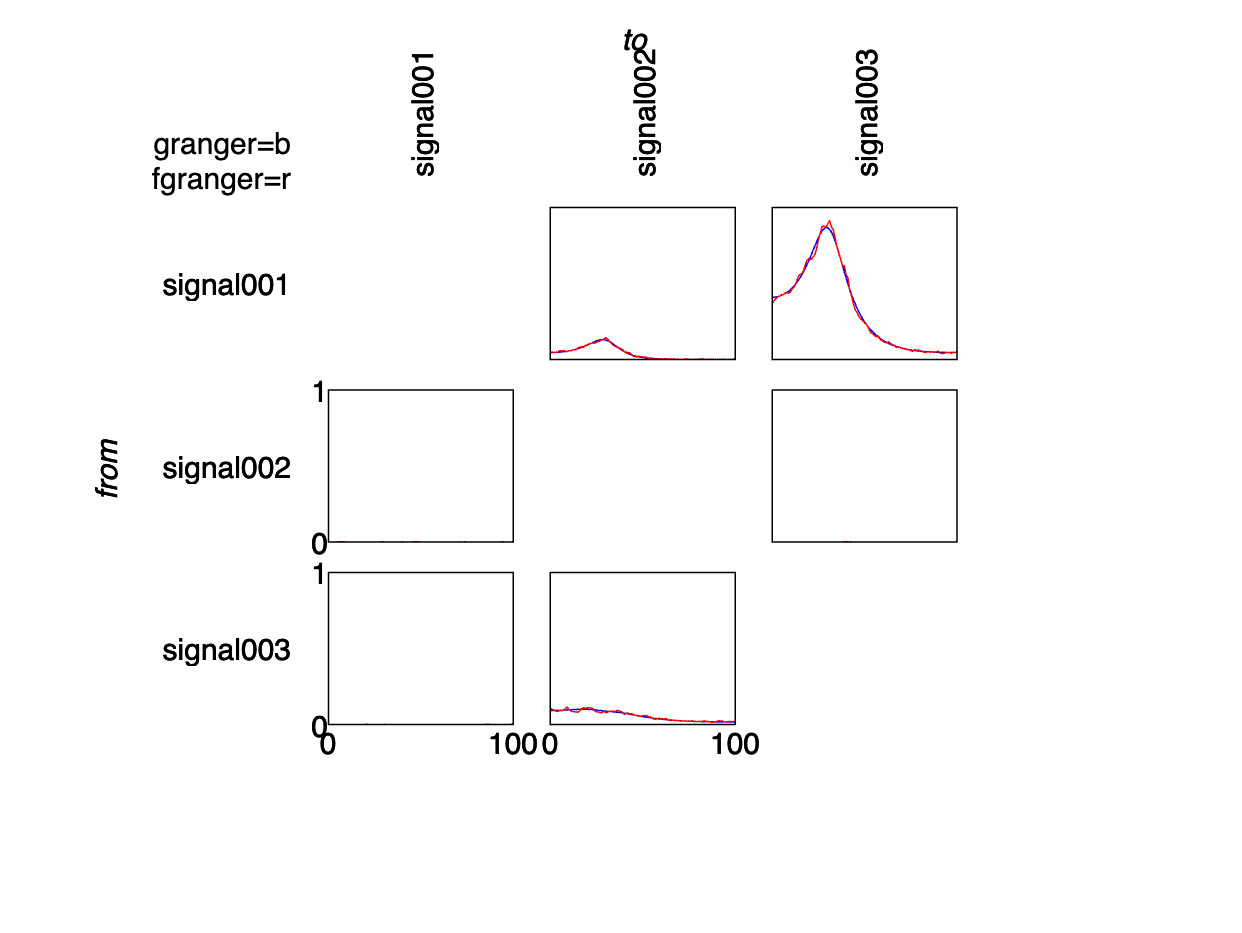

figure
cfg           = [];
cfg.method    = 'pdc';
mpdc       = ft_connectivityanalysis(cfg, mfreq);

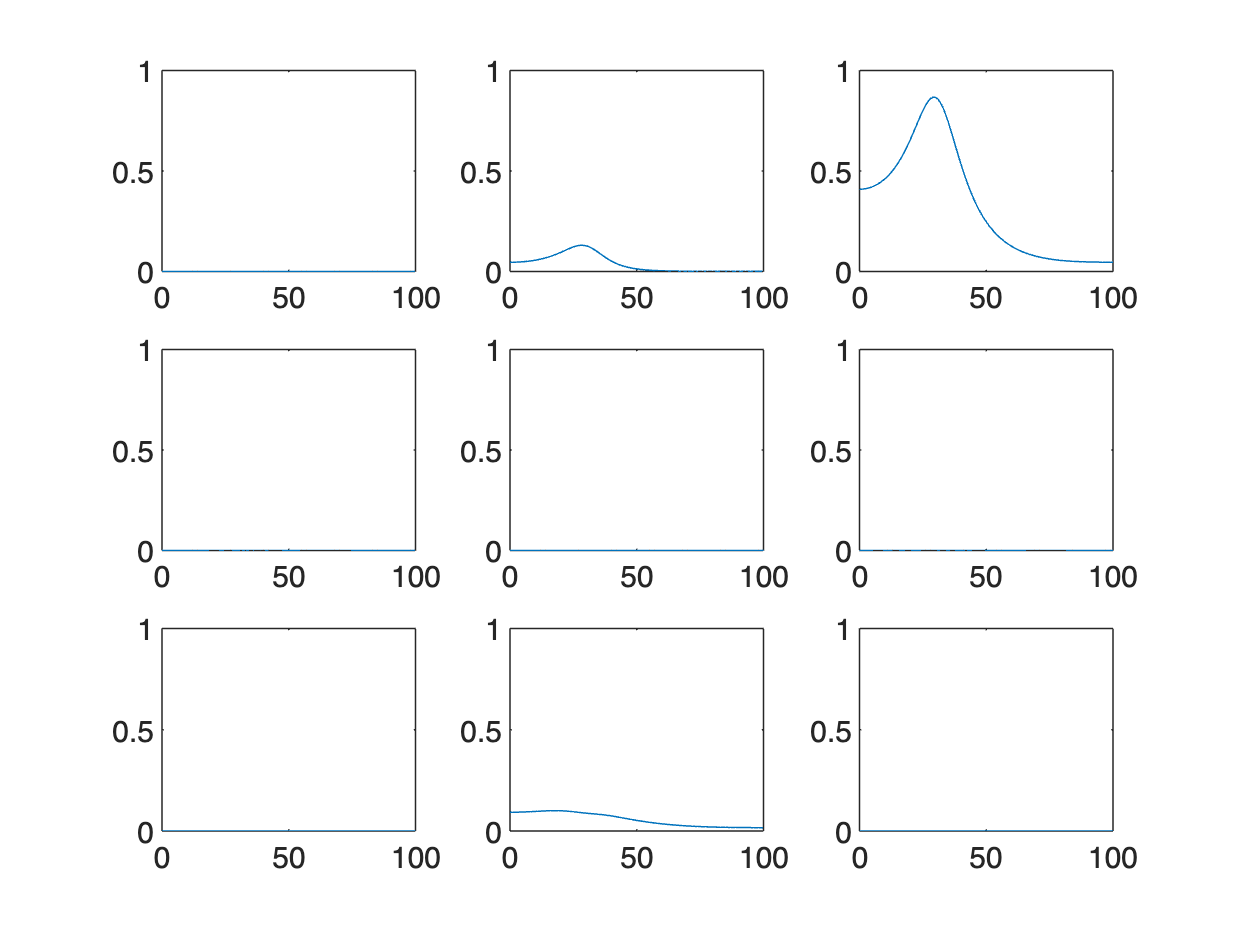


cfg           = [];
cfg.method    = 'pdc';
fpdc      = ft_connectivityanalysis(cfg, freq)
cfg           = [];
cfg.parameter = 'pdcspctrm';
cfg.zlim      = [0 1];


ft_connectivityplot(cfg, mpdc, fpdc);

**Notes: **

- PDC crushed it! It successfully resolved that the X->Y connection was not direct. I bet this is from the 'partialling out' steps. Also the connection from X->Z is not as tight as pure granger causality but the Z->Y connection does finally appear t o be comparable if not overall higher than the X->Z connection, which is super promising.

- Parametric looks much smoother here compared to the non-parametric

**Loading some real SEEG Data**

fpath = '/Users/user/Documents/MiniLab/000_Data/SEEG_Eyes_closed_resting_state/data/Spat53/Filtered_Chunks/First_Collection/All_2minChunks_Bipole_UnusedChannelsDeleted_Filtered/Spat53_Raw_bipole_unusedChannelsDeleted_Unfiltered_FILTERED_WITH_FIR_filtfilt_hamming_windowed_sinc_EEGlab_1-55_65-119Hz_chunk_0s_120s.edf'
filt_data = edfread(fpath);
size(filt_data)

cfg = [];

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB


cfg.dataset = char(fpath);
cfg.continuous = 'yes';
hdr = ft_read_header(char(fpath));
FT_data = ft_preprocessing(cfg);
label = FT_data.label;
FT_dataRef = cell2mat(FT_data.trial);
sampFreq = hdr.Fs; %get sampling rate from header
numChans = hdr.nChans;


cfg = [];
cfg.viewmode = 'vertical';  % you can also specify 'butterfly'
ft_databrowser(cfg, FT_data);

%computing MVAR coeffs
cfg = [];

fpath = '/Users/user/Documents/MiniLab/000_Data/SEEG_Eyes_closed_resting_state/data/Spat53/Filtered_Chunks/First_Collection/All_2minChunks_Bipole_UnusedChannelsDeleted_Filtered/Spat53_Raw_bipole_unusedChannelsDeleted_Unfiltered_FILTERED_WITH_FIR_filtfilt_hamming_windowed_sinc_EEGlab_1-55_65-119Hz_chunk_0s_120s.edf'

cfg.order = 5;
cfg.toolbox = 'bsmart';

ans =    120    85


%feeding in data from above simulation
mdata = ft_mvaranalysis(cfg, FT_data);
size(mdata.coeffs)
figure
for row=1:1
for col=1:5

processing channel { 'PT1 - PT2' 'PT2 - PT3' 'PT3 - PT4' 'PT4 - PT5' 'PT5 - PT6' 'PT6 - PT7' 'PT7 - PT8' 'PT8 - PT9' 'AH1 - AH2' 'AH2 - AH3' 'AH3 - AH4' 'AH9 - AH10' 'AH10 - AH11' 'AC1 - AC2' 'AC2 - AC3' 'AC3 - AC4' 'AC4 - AC5' 'AC7 - AC8' 'AC8 - AC9' 'AC9 - AC10' 'AC10 - AC11' 'AC11 - AC12' 'PH1 - PH2' 'PH2 - PH3' 'PH3 - PH4' 'PH5 - PH6' 'PH10 - PH11' 'PH11 - PH12' 'PH12 - PH13' 'PSI1 - PSI2' 'PSI2 - PSI3' 'PSI4 - PSI5' 'PSI5 - PSI6' 'PSI6 - PSI7' 'PSI7 - PSI8' 'PSI8 - PSI9' 'A1 - A2' 'A2 - A3' 'A3 - A4' 'A4 - A5' 'A5 - A6' 'A9 - A10' 'A10 - A11' 'A11 - A12' 'OF1 - OF2' 'OF3 - OF4' 'OF4 - OF5' 'OF5 - OF6' 'OF6 - OF7' 'OF8 - OF9' 'OF9 - OF10' 'OF10 - OF11' 'OF11 - OF12' 'PII1 - PII2' 'PII3 - PII4' 'PII4 - PII5' 'PII5 - PII6' 'PII6 - PII7' 'PII7 - PII8' 'PII8 - PII9' 'MSI1 - MSI2' 'MSI2 - MSI3' 'MSI3 - MSI4' 'MSI4 - MSI5' 'MSI5 - MSI6' 'MSI6 - MSI7' 'MSI7 - MSI8' 'AI1 - AI2' 'AI2 - AI3' 'AI3 - AI4' 'AI4 - AI5' 'AI5 - AI6' 'AI6 - AI7' 'AI7 - AI8' 'MII1 - MII2' 'MII4 - MII5' 'MII5 - MII6'

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

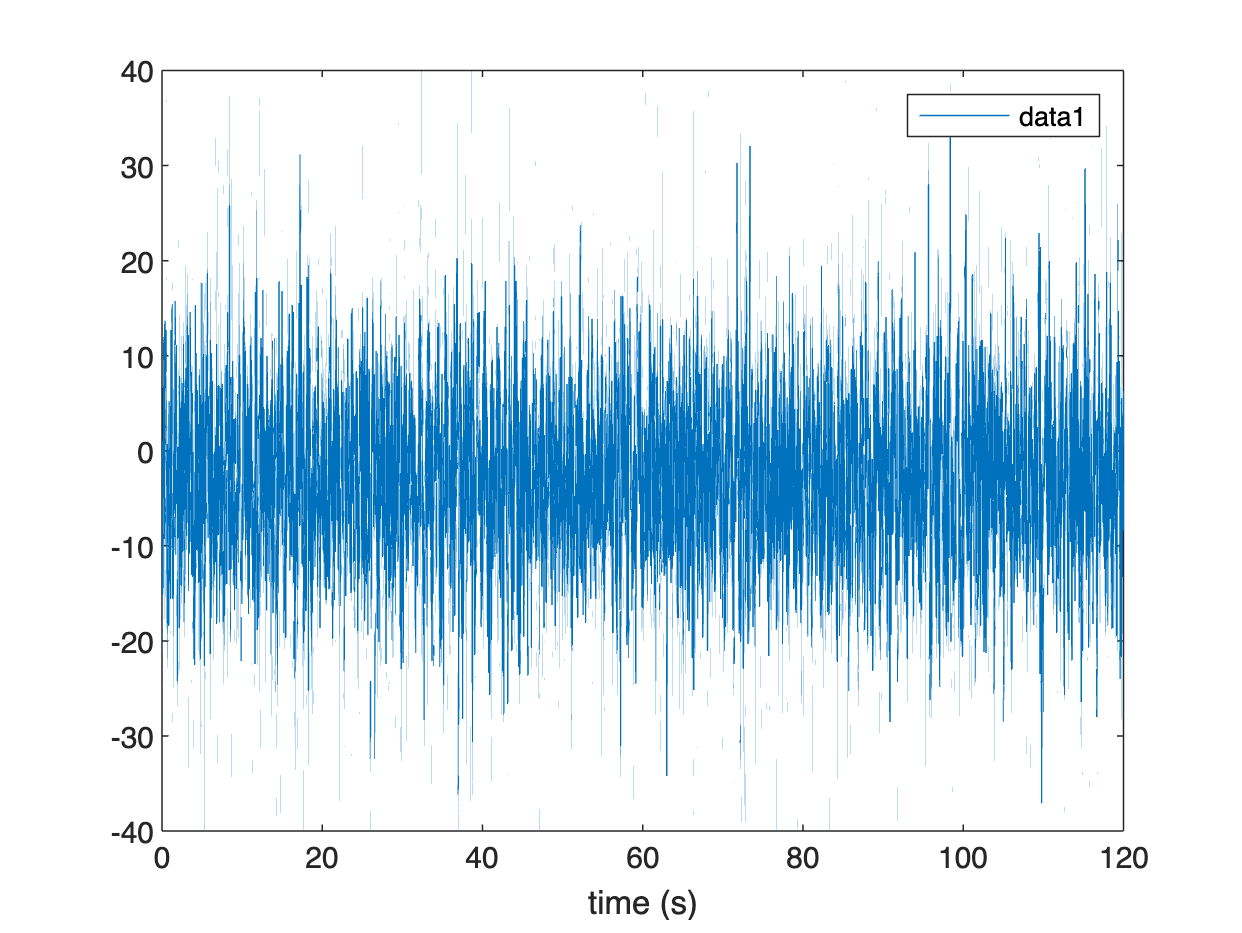

  subplot(1,5,(row-1)*5+col);
  imshow(mdata.coeffs(:,:,col))
end
end


the input is raw data with 85 channels and 1 trials
detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


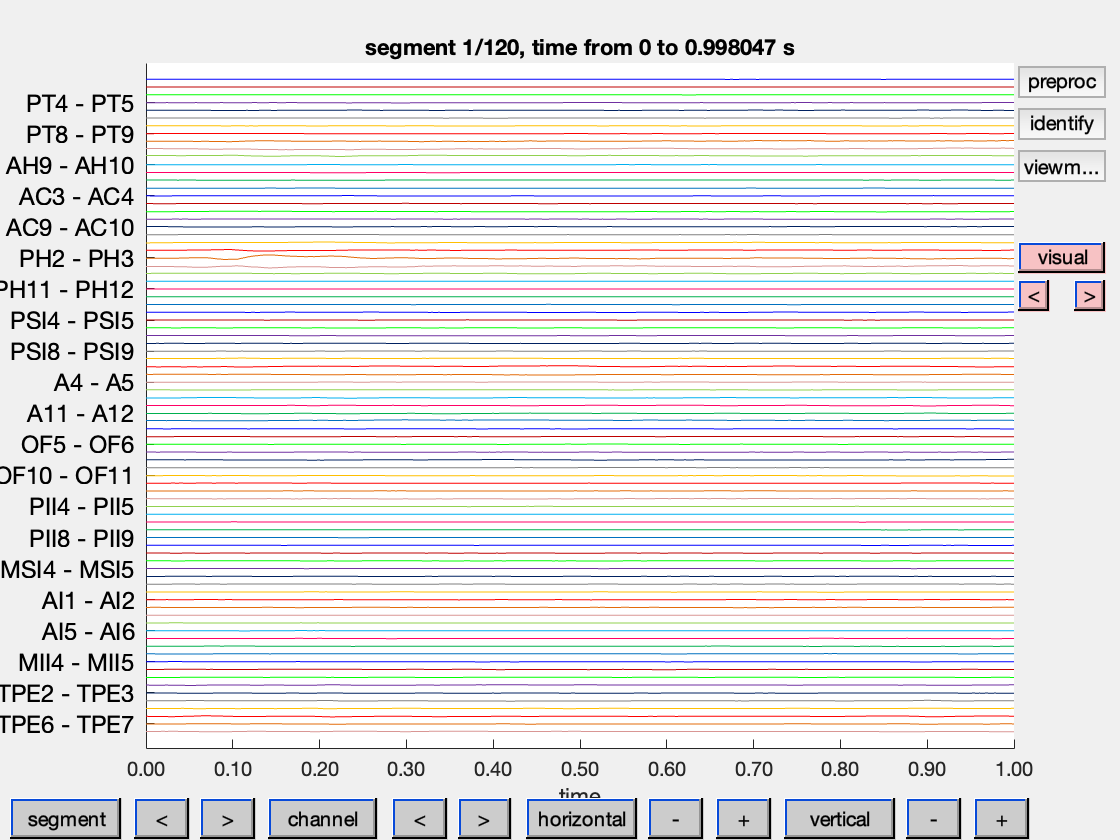

------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  : open vertical scaling dialog
p                  : open preproc editor
i                  : identify a specific channel
m                  : toggles between cfg.viewmode options
s                  : toggles between cfg.selec

%computing frequency decomps
cfg             = [];
cfg.method      = 'mvar';
mfreq           = ft_freqanalysis(cfg, mdata);

mfreq

%computing PDC
cfg           = [];
cfg.method    = 'pdc';
mpdc       = ft_connectivityanalysis(cfg, mfreq);

%plotting PDC
figure

 In ft_mvaranalysis at line 105

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated NaN MB

the call to "ft_mvaranalysis" took 1 seconds and required the additional allocation of an estimated NaN MB


cfg           = [];

ans =     85    85     5


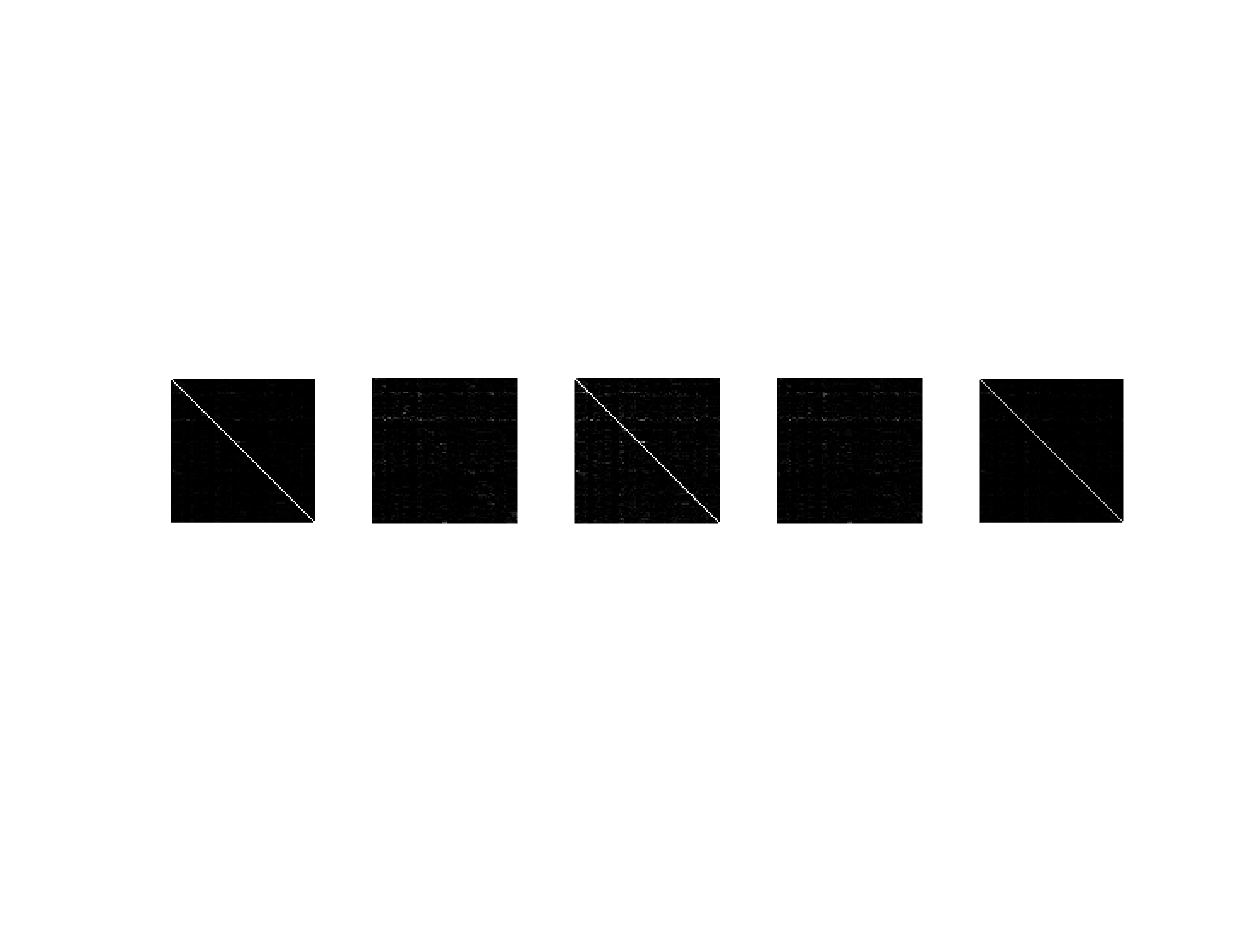

the input is mvar data
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
computing MAR-model based TFR
processing timewindow 1 from 1

the call to "ft_freqanalysis_mvar" took 5 seconds and required the additional allocation of an estimated NaN MB


mfreq = struct with fields:
         freq: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 … ] (1×257 double)
     transfer: [85×85×257 double]
     noisecov: [85×85 double]
    crsspctrm: [85×85×257 double]
          dof: 1
        label: {85×1 cell}
       dimord: 'chan_chan_freq'
          cfg: [1×1 struct]


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityanalysis" took 4 seconds and required the additional allocation of an estimated NaN MB


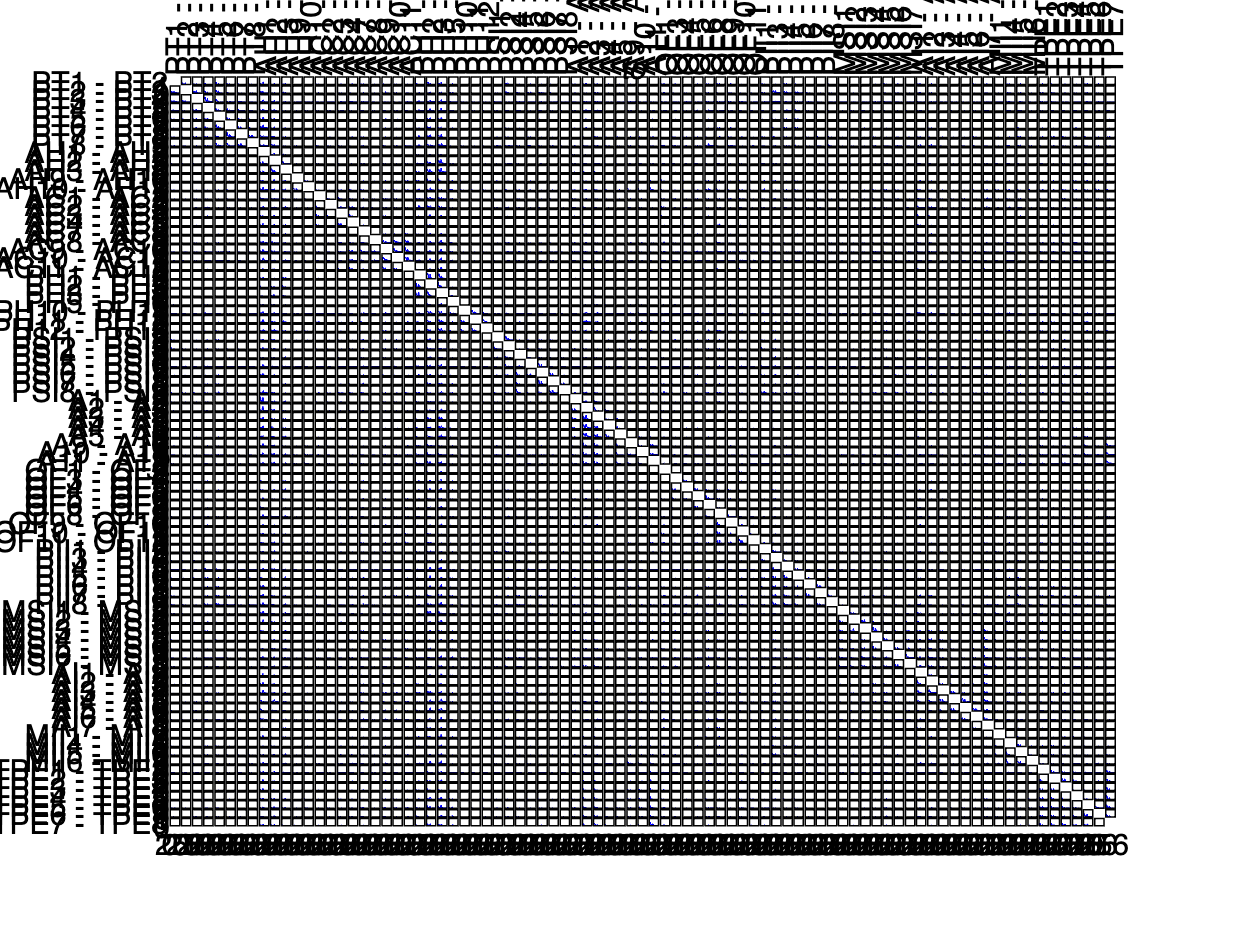

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated NaN MB
the call to "ft_connectivityplot" took 8 seconds and required the additional allocation of an estimated NaN MB


cfg.parameter = 'pdcspctrm';
cfg.zlim      = [0 1];


ft_connectivityplot(cfg, mpdc);